# MODELLIZZAZIONE E IDENTIFICAZIONE BRACCIOLO


clear; clc; close all;

Modellizzazione gray box

White box (fisica di base):

- Legge di Hooke (σ = Eε) per il gommino.

- Definizione di sforzo (σ = F/A) e deformazione (ε = ΔL/L₀).

- Formula della media pesata per il Centro di Pressione (CoP).

Black box (dati sperimentali) :

- Calibrazione del sensore Hall per ottenere la curva d=f(V)

- Stima del modulo di Young (E) tramite regressione lineare sui dati

Processo di modellizzazione 

- Statica: catena non lineare di calcolo: V → d → ΔL → F

- Dinamica: Introduciamo la dinamica del sistema con un filtro di Butterworth a tempo discreto, descritto da una funzione di trasferimento H(z)

- Linearizzazione:approssimazione del modello statico non-lineare a un modello lineare (guadagno K) attorno a un punto di lavoro, usando lo sviluppo in serie di taylor al primo ordine 

- Identificazione: Funzione di trasferimento combina il guadagno K con la dinamica del filtro H(z)

- Analisi e validazione: analisi tramite bode e risposta al gradino del modello linearizzato e confronto con la risposta del modello non lineare completo

## CARATTERIZZAZIONE DEI COMPONENTI

disp('CARATTERIZZAZIONE DEI COMPONENTI');

CARATTERIZZAZIONE DEI COMPONENTI


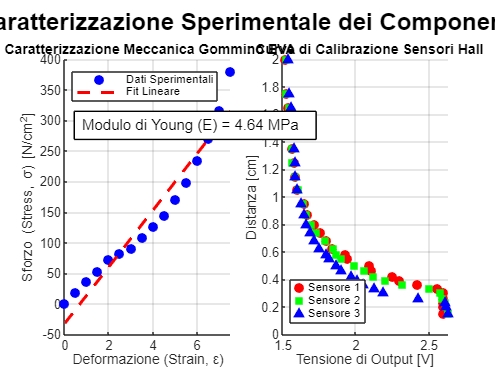


% Caratterizzazione Meccanica del Gommino EVA 
L0_cm = 1.0;
r_cm = 0.12;
A_cm2 = pi*r_cm^2;
forza_calib_N = [0 0.8 1.6 2.4 3.3 3.7 4.1 4.9 5.7 6.5 7.7 9.0 10.6 12.2 14.3 17.2];
distanza_unita_gommino = 0:10:150;
fattore_conversione_cm_unita = 0.5 / 10;
compressione_calib_cm = distanza_unita_gommino * fattore_conversione_cm_unita;
deformazione_strain = compressione_calib_cm / L0_cm;
sforzo_stress_N_cm2 = forza_calib_N / A_cm2;
p_fit_meccanico = polyfit(deformazione_strain(2:end), sforzo_stress_N_cm2(2:end), 1);
E_N_cm2 = p_fit_meccanico(1);
E_MPa = E_N_cm2 / 10;

% Calibrazione dei Sensori a Effetto Hall 
distanze_calib_sens_cm = [2.0; 1.75; 1.65; 1.5; 1.35; 1.25; 1.15; 1.05; 0.95; 0.87; 0.8; 0.74; 0.68; 0.62; 0.58; 0.55; 0.5; 0.46; 0.42; 0.39; 0.36; 0.33; 0.3; 0.26; 0.23; 0.2; 0.15];
tensione1_calib_V = [1.52; 1.53; 1.54; 1.55; 1.57; 1.58; 1.59; 1.6; 1.65; 1.67; 1.72; 1.76; 1.8; 1.84; 1.93; 1.94; 2.09; 2.11; 2.25; 2.3; 2.42; 2.56; 2.6; 2.6; 2.6; 2.6; 2.6];
tensione2_calib_V = [1.53; 1.53; 1.55; 1.56; 1.57; 1.57; 1.59; 1.61; 1.64; 1.66; 1.7; 1.73; 1.79; 1.85; 1.87; 1.9; 1.99; 2.06; 2.12; 2.2; 2.32; 2.5; 2.58; 2.59; 2.61; 2.62; 2.63];
tensione3_calib_V = [1.54; 1.55; 1.56; 1.56; 1.58; 1.59; 1.59; 1.6; 1.63; 1.65; 1.66; 1.69; 1.72; 1.75; 1.8; 1.82; 1.87; 1.9; 1.97; 2.01; 2.05; 2.13; 2.19; 2.43; 2.61; 2.62; 2.63];

% Grafici di Caratterizzazione 
figure('Name', 'Caratterizzazione dei Componenti del Sistema');
sgtitle('Caratterizzazione Sperimentale dei Componenti', 'FontSize', 16, 'FontWeight', 'bold');
% (Il codice per i grafici è corretto e rimane qui)
subplot(1, 2, 1);
hold on; grid on;
plot(deformazione_strain, sforzo_stress_N_cm2, 'ob', 'MarkerFaceColor', 'b', 'DisplayName', 'Dati Sperimentali');
plot(deformazione_strain, polyval(p_fit_meccanico, deformazione_strain), 'r--', 'LineWidth', 2, 'DisplayName', 'Fit Lineare');
xlabel('Deformazione (Strain, ε)'); ylabel('Sforzo (Stress, σ) [N/cm^2]');
title(' Caratterizzazione Meccanica Gommino EVA');
legend('show', 'Location', 'northwest');
text_str = sprintf('Modulo di Young (E) = %.2f MPa', E_MPa);
annotation('textbox', [0.15, 0.6, 0.2, 0.1], 'String', text_str, 'FitBoxToText', 'on', 'BackgroundColor', 'w');
hold off;
subplot(1, 2, 2);
hold on; grid on;
plot(tensione1_calib_V, distanze_calib_sens_cm, 'or', 'MarkerFaceColor', 'r', 'DisplayName', 'Sensore 1');
plot(tensione2_calib_V, distanze_calib_sens_cm, 'sg', 'MarkerFaceColor', 'g', 'DisplayName', 'Sensore 2');
plot(tensione3_calib_V, distanze_calib_sens_cm, '^b', 'MarkerFaceColor', 'b', 'DisplayName', 'Sensore 3');
xlabel('Tensione di Output [V]'); ylabel('Distanza [cm]');
title(': Curve di Calibrazione Sensori Hall');
legend('show', 'Location', 'southwest');
hold off;

## SVILUPPO DEL MODELLO MATEMATICO NON-LINEARE



disp(newline); disp(' SVILUPPO MODELLO MATEMATICO NON-LINEARE ');



 SVILUPPO MODELLO MATEMATICO NON-LINEARE 



% Modello Statico: dalla Tensione alla Forza 
create_interp = @(V,D) griddedInterpolant(unique(V), D(find(diff([inf; V(:)])~=0)), 'pchip', 'nearest');
V1_to_D = create_interp(tensione1_calib_V, distanze_calib_sens_cm);
V2_to_D = create_interp(tensione2_calib_V, distanze_calib_sens_cm);
V3_to_D = create_interp(tensione3_calib_V, distanze_calib_sens_cm);
System_NonLinear_V_to_F = @(v1,v2,v3) ...
    (E_N_cm2 * A_cm2 / L0_cm) * max(0, L0_cm - [V1_to_D(v1), V2_to_D(v2), V3_to_D(v3)]);

% Modello Dinamico: Filtro Butterworth 
fprintf('Modello Dinamico: Filtro Digitale Butterworth ---\n');

--- 3.2.2: Modello Dinamico: Filtro Digitale Butterworth ---


dt = 0.02;
fs = 1/dt;
filter_order = 4;
cutoff_freq_hz = 10;
wn = cutoff_freq_hz / (fs/2);
[b_butter, a_butter] = butter(filter_order, wn, 'low');
H_filter_tf = tf(b_butter, a_butter, dt);
fprintf('  - Funzione di Trasferimento del filtro H_filter(z):\n');

  - Funzione di Trasferimento del filtro H_filter(z):


disp(H_filter_tf);

  tf with properties:

       Numerator: {[0.0466 0.1863 0.2795 0.1863 0.0466]}
     Denominator: {[1 -0.7821 0.6800 -0.1827 0.0301]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.0200
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## IDENTIFICAZIONE DEL MODELLO LINEARE APPROSSIMATO


disp(newline); disp(' IDENTIFICAZIONE MODELLO LINEARE ');



 IDENTIFICAZIONE MODELLO LINEARE 



% Linearizzazione del Modello Statico 
V_op = 2.0;
delta_v = 1e-6;
F_op_plus = sum(System_NonLinear_V_to_F(V_op + delta_v, V_op + delta_v, V_op + delta_v));
F_op_minus = sum(System_NonLinear_V_to_F(V_op - delta_v, V_op - delta_v, V_op - delta_v));
K_static_total = (F_op_plus - F_op_minus) / (2 * delta_v);

% Derivazione della Funzione di Trasferimento 
H_system_linearized_tf = H_filter_tf * K_static_total;
fprintf(' Derivazione della Funzione di Trasferimento H(z) ---\n');

 Derivazione della Funzione di Trasferimento H(z) ---


fprintf('La Funzione di Trasferimento identificata è:\n');

La Funzione di Trasferimento identificata è:


disp(H_system_linearized_tf);

  tf with properties:

       Numerator: {[0.1466 0.5864 0.8796 0.5864 0.1466]}
     Denominator: {[1 -0.7821 0.6800 -0.1827 0.0301]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.0200
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## ANALISI E VALIDAZIONE DEL MODELLO IDENTIFICATO

disp(newline); disp('ANALISI E VALIDAZIONE ');



ANALISI E VALIDAZIONE 


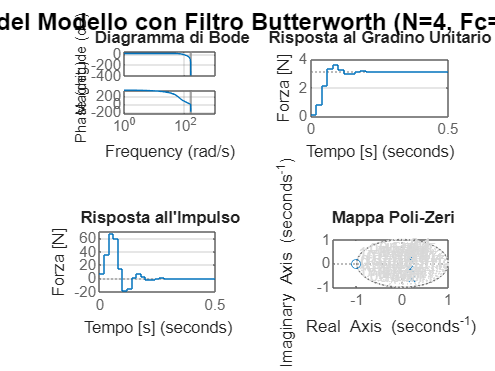


% Analisi del Modello Linearizzato (con Butterworth) 
figure('Name', ' Analisi del Modello Linearizzato (Butterworth)');
sgtitle(sprintf('Analisi del Modello con Filtro Butterworth (N=%d, Fc=%.1fHz)', filter_order, cutoff_freq_hz), 'FontSize', 16, 'FontWeight', 'bold');
subplot(2,2,1); bode(H_system_linearized_tf); grid on; title(' Diagramma di Bode');
subplot(2,2,2); step(H_system_linearized_tf); grid on; title('Risposta al Gradino Unitario'); ylabel('Forza [N]'); xlabel('Tempo [s]');
subplot(2,2,3); impulse(H_system_linearized_tf); grid on; title(' Risposta all''Impulso'); ylabel('Forza [N]'); xlabel('Tempo [s]');
subplot(2,2,4); pzmap(H_system_linearized_tf); grid on; title(' Mappa Poli-Zeri');

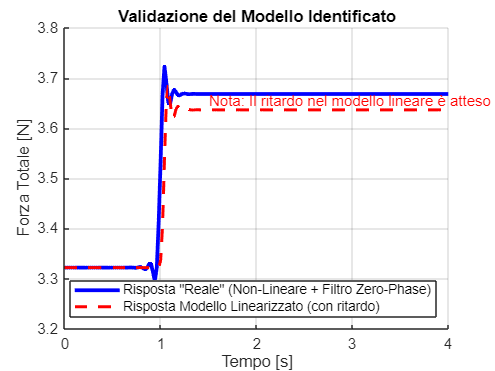


% --- 4.2: Validazione del Modello (usando filtfilt per il confronto) ---
t_val = (0:dt:4)';
v_step_amplitude = 0.1;
v_input_step = V_op + (t_val >= 1) * v_step_amplitude;
v_input_filtered = filtfilt(b_butter, a_butter, v_input_step);
F_nonlinear_response = zeros(size(t_val));
for i = 1:length(t_val)
    F_nonlinear_response(i) = sum(System_NonLinear_V_to_F(v_input_filtered(i), v_input_filtered(i), v_input_filtered(i)));
end
[F_linear_response, ~, ~] = lsim(H_system_linearized_tf, v_input_step - V_op, t_val);
F_linear_response = F_linear_response + sum(System_NonLinear_V_to_F(V_op,V_op,V_op));
figure('Name', ' Validazione del Modello Linearizzato (Butterworth)');
hold on; grid on;
plot(t_val, F_nonlinear_response, 'b', 'LineWidth', 2.5, 'DisplayName', 'Risposta "Reale" (Non-Lineare + Filtro Zero-Phase)');
plot(t_val, F_linear_response, 'r--', 'LineWidth', 2, 'DisplayName', 'Risposta Modello Linearizzato (con ritardo)');
xlabel('Tempo [s]'); ylabel('Forza Totale [N]');
title('Validazione del Modello Identificato');
legend('show', 'Location', 'southeast');
text(1.5, min(F_linear_response)*1.1, 'Nota: Il ritardo nel modello lineare è atteso', 'Color', 'red');
hold off;